## Exo 1

N=100;
u0=0;u1=-1;
h=1/(N+1);
un=ones(N-1,1);
A=1/h^2*(2*eye(N)-diag(un,-1)-diag(un,1));
c=inline('x');
f=inline('(x.^2+pi^2.*x).*cos(pi.*x)+2*pi*sin(pi.*x)');
B=diag(c(h*[1:N]));
F=[f(h*[1:N]')];
F(1,1)=F(1,1)+u0/h^2;
F(N,1)=F(N,1)+u1/h^2;
M=A+B;
U=M\F

U =     0.0099
    0.0198
    0.0296
    0.0393
    0.0489
    0.0584
    0.0677
    0.0768
    0.0857
    0.0943


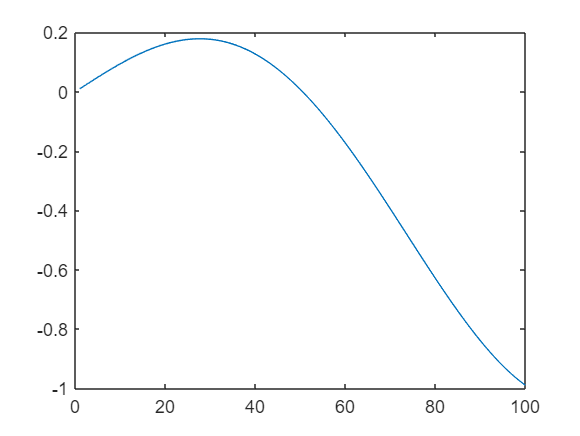

plot(U)

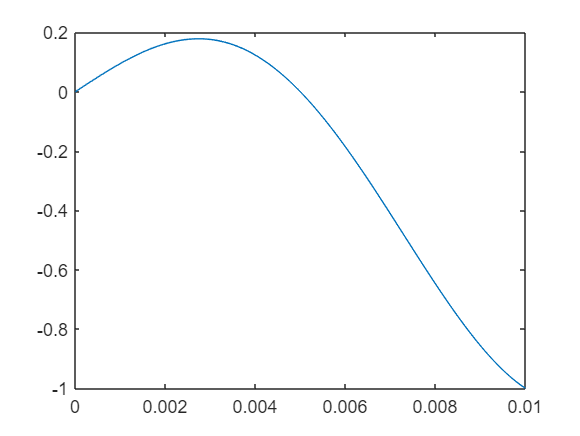


g=inline('100*x.*cos(pi*100*x)');
plot(linspace(0,1/N,N),g(linspace(0,1/N,N)))

## Exo 4

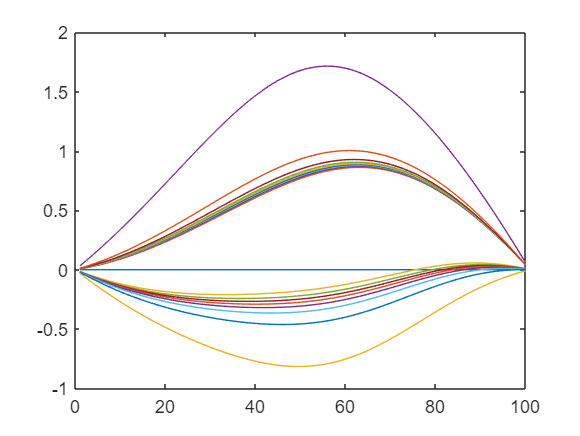

n=100;
H=1/(n+1);
UN=ones(n-1,1);
J=1/h^2*(2*eye(n)-diag(UN,-1)-diag(UN,1));%A
alpha=23;
d=inline('x.*pi^2.*sin(pi*x)-2*pi*cos(pi*x)+23*(x.*sin(pi*x)).^3');%f
u=inline('x.*sin(x*pi)');%u reponse
D=[d(H*[1:n]')];%F
K=zeros(n);%U
for i=2:n
    K(:,i)=inv(J)*(D-alpha.*K(:,i-1).^3);
end
plot(K(:,1:18))

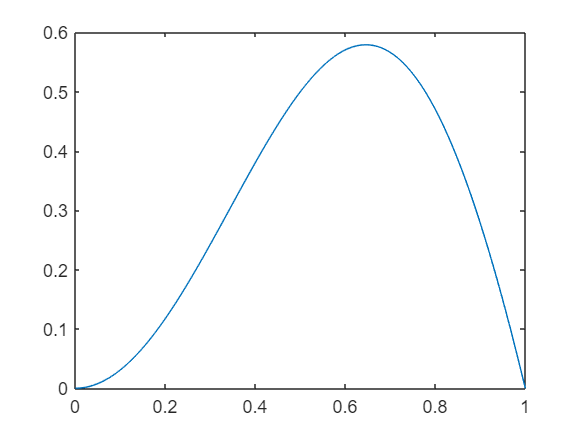


plot(linspace(0,1,n),u(linspace(0,1,n)))